# 6주차 과제 — 근궤적 기초

**제어시스템설계** · 충남대학교 자율운항시스템공학과

문제는 **세 개**입니다.

- **1. 몸풀기** (쉬움 · 수업 중 10분 · 30점) — 궤적 모양을 손으로 예측

- **2. 기본** (중간 · 40분 · 70점) — 근궤적으로 이득 하나 고르기

- **3. 도전** (선택 · 가산점 10점) — 구동기 한계를 넣으면

**3번은 선택입니다.** 1번과 2번만 해도 만점입니다.

clc; close all;
s = tf('s');

## 1. 몸풀기 — 그리기 전에 모양을 맞혀 보기

**강의노트 3절과 4절을 그대로 보면 됩니다.**

근궤적은 **이득 **$K$** 를 **$0$** 에서 **$\infty$** 로 키울 때 폐루프 극점이 지나가는 길**입니다.

그리기 전에 세 가지를 손으로 알 수 있습니다.

- **가지 개수** = 개루프 극점 개수 $n$

- **출발점** = 개루프 **극점**, **도착점** = 개루프 **영점** (모자라면 무한대로)

- **점근선** — 무한대로 가는 가지가 향하는 방향


$$\sigma_a = \frac{\sum(\text{극점}) - \sum(\text{영점})}{n-m}, \qquad \theta_a = \frac{(2q+1)\,180^{\circ}}{n-m}$$


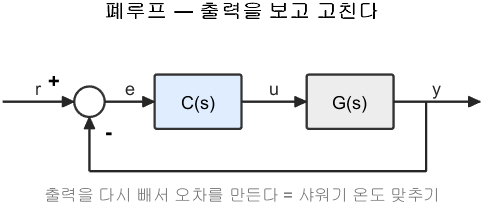

폐루프 — 출력을 보고 고친다

**그림 파일** `loop_closed.png` — `common/dg_loop.m` 의 `dg_loop` · 다시 만들려면 `make_figures('loop_closed')`

## 1-1. 손으로 채우기

아래 네 개루프에 대해 $n$, $m$, $n-m$, $\sigma_a$, $\theta_a$ 를 손으로 구하십시오.


$$L_a = \frac{1}{(s+1)(s+3)}, \qquad L_b = \frac{1}{s(s+1)(s+3)}$$



$$L_c = \frac{s+2}{s(s+1)(s+3)}, \qquad L_d = \frac{1}{s(s+1)(s+3)(s+5)}$$


그다음 `TODO` 두 줄을 채워 확인하십시오.

Ls = { 'La', 1/((s+1)*(s+3))
       'Lb', 1/(s*(s+1)*(s+3))
       'Lc', (s+2)/(s*(s+1)*(s+3))
       'Ld', 1/(s*(s+1)*(s+3)*(s+5)) };

fprintf('  이름   n   m  n-m   sigma_a    점근선 각도\n');
fprintf('  ----  --  --  ---  --------  ----------------\n');
for i = 1:4
    L  = Ls{i,2};
    n_ = NaN;    % TODO : numel(pole(L)) 로 극점 개수를 구하십시오
    m_ = NaN;    % TODO : numel(zero(L)) 로 영점 개수를 구하십시오
    if isnan(n_) || isnan(m_)
        fprintf('  %-4s  (아직 안 채움)\n', Ls{i,1});
        continue
    end
    sg = (sum(pole(L)) - sum(zero(L)))/(n_ - m_);
    th = (2*(0:(n_-m_-1)) + 1)*180/(n_ - m_);
    fprintf('  %-4s  %2d  %2d  %3d  %8.3f  ', Ls{i,1}, n_, m_, n_-m_, real(sg));
    fprintf('%.0f ', th);
    fprintf('\n');
end

## 1-2. 그림으로 확인

코드는 다 되어 있습니다. 손 예측과 맞는지 보십시오.

figure;
tiledlayout(2,2,'TileSpacing','compact');
for i = 1:4
    nexttile
    rlocus(Ls{i,2}); grid on;
    xlim([-8 3]); ylim([-6 6]);
    title(Ls{i,1});
end

## 1-3. 답할 것 (두 문장이면 됩니다)

- $L_b$ 와 $L_c$ 를 비교하십시오. 영점 하나를 더했더니 궤적이 어느 쪽으로 갔는가?

- 네 개 중 **불안정해질 수 있는 것**은 어느 것인가? (그림에서 오른쪽으로 넘어가는 것)

## 2. 기본 — 근궤적으로 이득 고르기

**강의노트 6절부터 8절까지를 그대로 보면 됩니다.**

플랜트와 사양은 이렇습니다.


$$G(s) = \frac{1}{s(s+2)(s+8)}$$


- 오버슈트 $\le 20\%$

- 정착시간 $\le 4$ 초

설계 절차는 다섯 단계입니다. 하나씩 밟습니다.

G = 1/(s*(s+2)*(s+8));

## 2-1. 1단계 : 사양을 $s$ 평면으로

`spec2pole` 을 쓰면 됩니다. 실행만 하면 됩니다.

P_OS = 20;  ts = 4;
[zmin, wmin, starget] = spec2pole(P_OS, ts);
fprintf('\n=== 1단계 ===\n');
fprintf('  zeta >= %.4f , wn >= %.4f\n', zmin, wmin);
fprintf('  목표 극점 : %+.3f %+.3fj\n', real(starget), imag(starget));

## 2-2. 2단계 : 궤적과 사양 영역을 겹쳐 그리기

`sgrid` 는 반드시 `rlocus` **다음에** 불러야 합니다. 코드는 다 되어 있습니다.

figure;
rlocus(G); hold on;
sgrid(zmin, wmin);
plot(real(starget), imag(starget), 'p', 'MarkerSize', 16, ...
     'MarkerFaceColor', 'm', 'MarkerEdgeColor', 'k');
xlim([-12 3]); ylim([-8 8]); grid on;
title('궤적과 사양 영역 (별표 = 목표 극점)');

## 2-3. 3단계 : 사양을 만족하는 이득 찾기

6주차에서는 `rlocfind` 로 마우스를 찍었습니다. 여기서는 `rl_scan` 으로 숫자를 훑습니다. 결과가 재현되고 표로 남습니다.

- **입력** `rl_scan(C1, G, Kvec)`. `C1` 은 이득을 뺀 제어기이므로 비례제어면 `1`

- **출력** `K stable zeta wn OS ts Tp ess umax` 열을 가진 표

`TODO` 한 줄만 채우십시오.

T = rl_scan(1, G, linspace(0.5, 60, 600), true);
ok = NaN;    % TODO : T.stable & T.OS <= P_OS & T.ts <= ts 로 논리 벡터를 만드십시오

if islogical(ok) && any(ok)
    fprintf('\n=== 3단계 ===\n');
    fprintf('  사양을 만족하는 이득 : K = %.2f ~ %.2f\n', min(T.K(ok)), max(T.K(ok)));
    sub = T(ok,:);
    fprintf('     K     OS[%%]   ts[s]   max|u|\n');
    fprintf('  ------  ------  ------  -------\n');
    for i = round(linspace(1, height(sub), 4))
        fprintf('  %6.2f  %6.2f  %6.2f  %7.2f\n', ...
                sub.K(i), sub.OS(i), sub.ts(i), sub.umax(i));
    end
end

## 2-4. 4단계 : 하나 골라 검증

위 구간의 **가운데쯤** 값을 하나 고르십시오. 그다음 `stepinfo` 로 확인합니다.

`TODO` 한 줄을 채우십시오.

K_pick = NaN;    % TODO : 위에서 찾은 구간 안의 값을 하나 고르십시오 (예: 14)

if ~isnan(K_pick)
    Tcl = feedback(K_pick*G, 1);
    info = stepinfo(Tcl);
    fprintf('\n=== 4단계 : 검증 (K = %.2f) ===\n', K_pick);
    fprintf('  오버슈트 %.2f %%  (요구 %.0f 이하)\n', info.Overshoot, P_OS);
    fprintf('  정착시간 %.3f s   (요구 %.0f 이하)\n', info.SettlingTime, ts);
    fprintf('  폐루프 극점 : %s\n', mat2str(round(pole(Tcl).', 3)));

    t2 = (0:0.01:8)';
    [u2, ~] = ctrl_input(K_pick, G, t2);
    figure;
    tiledlayout(1,2,'TileSpacing','compact');
    nexttile
    plot(t2, step(Tcl, t2), 'LineWidth', 2); hold on;
    yline(1,'k--'); yline(1+P_OS/100,'r:'); xline(ts,'r:');
    grid on; xlabel('시간 [s]'); ylabel('출력');
    legend('출력','목표','오버슈트 한계','정착시간 한계','Location','southeast');
    title('계단응답');
    nexttile
    plot(t2, u2, 'LineWidth', 2); grid on;
    xlabel('시간 [s]'); ylabel('제어입력 u');
    title('제어입력도 반드시 본다');
end

## 2-5. 답할 것 (세 문장이면 됩니다)

- 사양 구간의 **아래쪽 한계**를 정한 것은 어느 사양인가? **위쪽**은?

- 고른 $K$ 에서 폐루프 극점이 셋인데, 그중 **지배극점**은 어느 것인가?

- 최대 제어입력은 얼마인가? 실제 구동기가 이 값을 낼 수 있어야 한다

## 3. 도전 (선택) — 구동기 한계가 있으면

**이 문제는 선택입니다. 안 해도 만점입니다.** 가산점 10점입니다.

실제 구동기는 정해진 값까지만 냅니다.

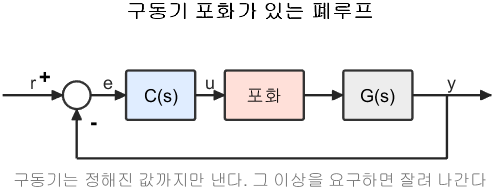

구동기 포화가 있는 폐루프

**그림 파일** `loop_saturation.png` — `common/dg_loop.m` 의 `dg_loop` · 다시 만들려면 `make_figures('loop_saturation')`

할 일

- 2번의 표에 이미 `umax` 열이 있습니다. $|u| \le 10$ 이라는 조건을 추가하면 사양을 만족하는 $K$ 구간이 어떻게 줄어드는지 구하라

- 그 구간이 비어 있지 않다면 그중 하나를 골라 검증하라

답할 것 (두 문장)

- 비례제어에서 최대 제어입력이 왜 $K$ 와 같은가?

- 구동기 한계가 $5$ 였다면 사양을 만족할 수 있겠는가?

TODO : 여기에 코드를 작성하십시오

## 채점 기준

- **1. 몸풀기** 30점 — 손 예측과 그림이 맞는가, 두 질문에 답했는가

- **2. 기본** 70점 — 네 단계와 검증, 세 질문에 답했는가

- **3. 도전** 가산점 10점

감점 사항 (세 가지뿐입니다)

- 제어입력을 확인하지 않은 경우

- 축 이름이나 범례가 없는 그림

- 코드가 오류로 멈추는 경우